# **Digital Communications TTT4130 - Matlab Lab Sessions**

**Lab Responsible**: Johan Suarez (johan.suarez@ntnu.no)

`Prerequisites`

Up-to-date installation of `MATLAB `and `SIMULINK `including `Communications Toolbox. (NTNU students receive Campus license)`

`Instructions`

**All lab sessions are group projects. Groups will be assigned randomly and consist of 2-3 people.** 

This is a Matlab live script. The script will guide through the lab session with coding tasks accompanied by explanations and comments.

**Please download and install MATLAB/Simulink and include the Communications toolbox as add-in. **

**You are free to use any resource you think is useful. Collaboration and discussion between groups is encouraged. **

# `Project 3 - Channel Coding`

### `Digital Communication System Schematic`

# 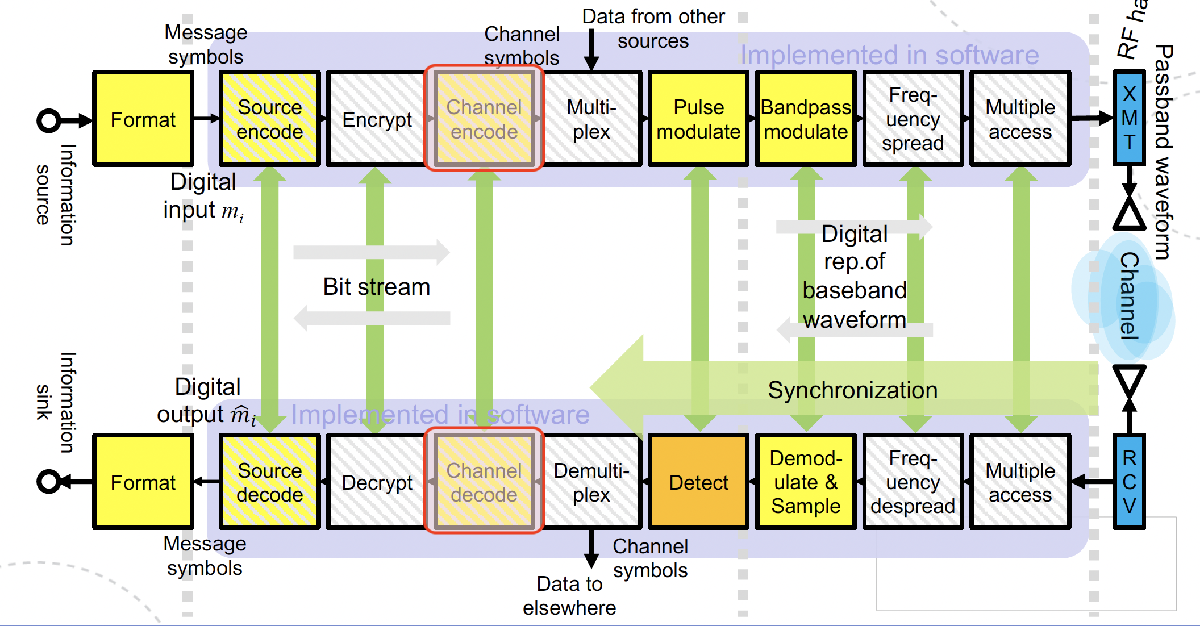

Specifically, the lab session covers the highlighted (red) parts of the schematic depicted above. 

### `Course Content`

- Coding Gain

- Convolutional Codes

- Cyclic redundancy check

- Bit interleaved coded modulation

#### `Task 1 : Hamming Code`

This task illustrates the principle of *block codes*. 

- Generator Matrix

- Parity Check Matrix

- Syndrome

Recomended reading: Section 6.4 *Linear Block Codes *in *Digital Communications, Sklar*

% Tip: Use MatLab inbuilt functions whenever possible 


% Define message length k and codeword length n 
n = 7; k = 4;     

% Generate random binary message of length k
m = randi([0,1], 1, k);
m


% Generate parity check matrix and generator matrix using hammgen()
[h,g] = hammgen(3);
h
g

% Encode the message using encode()
em  = encode(m,n,k);
em, m
%  Use the first column of the codes STANDARD ARRAY to construct the error

m =      0     1     0     1


%  pattern -> syndrome LUT

%  creating error message
errors = eye(n);
em

h =      1     0     0     1     0     1     1
     0     1     0     1     1     1     0
     0     0     1     0     1     1     1


erroredMessage = mod(em + errors(:,1)',2);

g =      1     1     0     1     0     0     0
     0     1     1     0     1     0     0
     1     1     1     0     0     1     0
     1     0     1     0     0     0     1


erroredMessage
syndrome = mod(h * erroredMessage',2);
syndrome, erroredMessage, h


em =      1     1     0     0     1     0     1


m =      0     1     0     1


% Introduce 1-bit errors at different positions in the codeword and calculate the
% syndrome of the error

% making matrix with one error on every index
% Flip 1 bit
errorAtAllPos = mod(errors + em,2);

em =      1     1     0     0     1     0     1


syndromes = mod(h * errorAtAllPos',2);


erroredMessage =      0     1     0     0     1     0     1


% Decode using created LUT & check if 1-bit error can be successfully
% decoded

syndrome =      1
     0
     0


erroredMessage =      0     1     0     0     1     0     1


h =      1     0     0     1     0     1     1
     0     1     0     1     1     1     0
     0     0     1     0     1     1     1


h,syndromes(:,2)
%Usig the LUT
[~, idx] = ismember(syndromes', h', "rows");
errorAtAllPos,em, idx
for i = 1:n
    errorAtAllPos(i,idx(i)) = mod(errorAtAllPos(i,idx(i)) + 1,2);
end
errorAtAllPos, em


% ------------------------------------------------- %


h =      1     0     0     1     0     1     1
     0     1     0     1     1     1     0
     0     0     1     0     1     1     1


ans =      0
     1
     0


% Flip 2 bits at different positions and check if the erraneous codeword
% can be successfully decoded


errorAtAllPos =      0     1     0     0     1     0     1
     1     0     0     0     1     0     1
     1     1     1     0     1     0     1
     1     1     0     1     1     0     1
     1     1     0     0     0     0     1
     1     1     0     0     1     1     1
     1     1     0     0     1     0     0


em =      1     1     0     0     1     0     1


idx =      1
     2
     3
     4
     5
     6
     7



% Decode with Matlab inbuilt functions and confirm your findings from above


#### `Task 2 : Convolutional Encoder & Decoder`

- Convolutional Encoding

- Convolutional Code Parameters

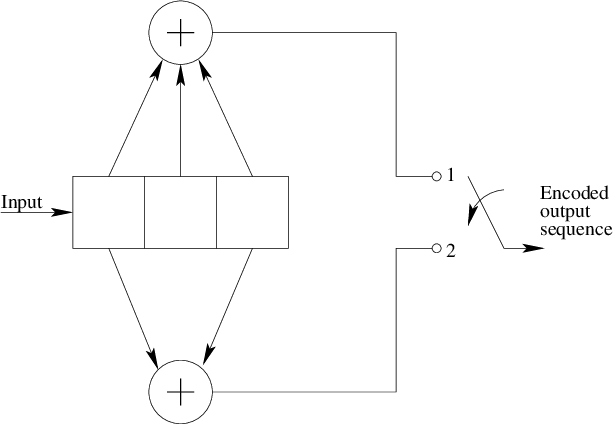

Determine the convolutional coding parameters from the schematic above. Then implement the convolutional encoder for a binary sequence of your choice. 

If you decide to use a non continous message bit stream (i.e., a message of specific length) *flush *the registers. 

*(refer to p. 378ff Digital Communcations, Sklar)*

% Implement the Convolutional Decoder and encode a binary message 

errorAtAllPos =      1     1     0     0     1     0     1
     1     1     0     0     1     0     1
     1     1     0     0     1     0     1
     1     1     0     0     1     0     1
     1     1     0     0     1     0     1
     1     1     0     0     1     0     1
     1     1     0     0     1     0     1


em =      1     1     0     0     1     0     1




k = 4

% Encode using the built-in convolutional encoder for comparison



#### `Task 3 : Cyclic Redundancy Check - CRC`

Now use a CRC encoder on your message.

Obtain an estimate for the error detection capability of the CRC, i.e. what is the probability of missed error detection of the CRC, and the overhead introduced.

% Original message


% CRC encode


% Convolutional encode (Task 2 function, or matlab built-in function)


% Simulate channel — introduce errors


% Viterbi decode


% CRC check — did Viterbi recover everything correctly?


`Task 4: Interleaving`

Realise a system that utilises convolutional coding and eventually cyclic redundancy checks to correct and detect errors in transmission.

Document the minimum separation achieved by the interleaver.

% Message + CRC


% Convolutional encoding


% Interleaving


% 16-QAM modulation. Note: needs groups of 4 bits, Matlab function qammod()


% Channel — AWGN


% Demodulation


% De-interleaving


% Viterbi decoding


% CRC check


% BER count



Check BER at 10dB, and 5dB

#### `Task 5: Coding Gain`

Compare the BER vs SNR performance of     

- Hamming codes

- Convolutional codes w/ hard-, and soft decoding

This is an unguided exercises. It is recommended to use Matlab inbuilt functions wherever possible. 

% Implementation
